# Práctica 10: Rotación de una imagen

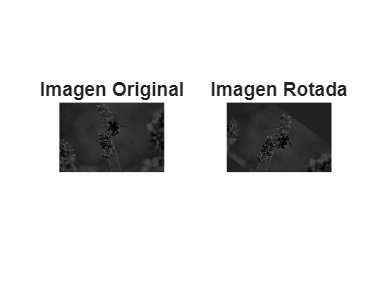

% Cargar imagen
img = imread("gammagrafia.png");
img_gray = rgb2gray(img);

% Tamaño imagen
[y, x] = size(img_gray);

% Punto de rotación
puntox = x/3;
puntoy = y/2;

% Angulo de rotacion en radianes
angulo_rad = deg2rad(37); 

% Crear imagen rotada e inicializar los pixeles con el color del primero
img_rotada = ones(y, x) * double(img_gray(1, 1)); 

% Iterar sobre cada píxel de la nueva imagen
for i = 1:y
    for j = 1:x
        % Fórmula de rotación
        x_origen = puntox + ((j - puntox) * cos(angulo_rad) + (i - puntoy) * sin(angulo_rad));
        y_origen = puntoy + (-(j - puntox) * sin(angulo_rad) + (i - puntoy) * cos(angulo_rad));
        
        % Interpolación
        x_origen = round(x_origen);
        y_origen = round(y_origen);
        
        % Verificar si las coordenadas están dentro del tamaño de la imagen
        if x_origen >= 1 && x_origen <= x && y_origen >= 1 && y_origen <= y
            img_rotada(i, j) = img_gray(y_origen, x_origen);
        end
    end
end

figure;
subplot(1, 2, 1), imshow(img_gray), title('Imagen Original');
subplot(1, 2, 2), imshow(uint8(img_rotada)), title('Imagen Rotada');